Ejemplos en MATLAB:

a.- Polinomio mal condicionado:

Polinomio de Wilkinson: 

clear
clc
p= poly(1:20);   % genera polinomio cuyas raíces son : 1, 2, 3,……, 19, 20
roots(p)	  % calcula las raíces

p(3)= p(3) + 1.e-10;  % modificamos el coeficiente 18 del polinomio
		         % Nota en MATLAB los polinomios se almacenan : 
                 % p2(x) = 1+2x+3x^2  --  p=[3  2 1]
roots(p)           % calcula las raíces del polinomio perturbado
p(3)= p(3) + 1.e-8 % modificamos el coeficiente 18 del polinomio
roots(p)            % calcula las raíces del polinomio perturbado

Nota: observa el error en las raíces al perturbar el coeficiente 18 del polinomio.

 b.- Proceso inestable: Resolución de una ecuación de segundo grado:  a x^2+ b x + c =0.

Algoritmo 1:  x=(-b  ± ( b^2-4ac)^1/2) / (2a)                                     ---      Algoritmo inestable 

a=eps;b=10;c=-10;
x1=(-b+sqrt(b^2-4*a*c))/(2*a)
x2=(-b-sqrt(b^2-4*a*c))/(2*a)
p1=poly([x1 x2])
roots(p1)

Algoritmo 2: x1=(-b-sg (b) (b^2-4ac)^1/2  ) / (2a)    y      x2 = c /(ax1)      ------ Algoritmo estable

xx1=(-b-sign(b)*sqrt((b^2-4*a*c)))/(2*a) 
xx2=c/(a* xx1)
p2=poly([xx1 xx2])
roots(p2)

**c.- Matrices mal condicionadas.**

a.- Utiliza las matrices de Hilbert (help MATLAB, [https://es.wikipedia.org/wiki/Matriz_de_Hilbert](https://es.wikipedia.org/wiki/Matriz_de_Hilbert)) y calcula el número de condición para diferentes tamaños de matriz y representa en un  gráfico su evolución. 

n=20;
vecCond=zeros(n-1,1);
for i=2:n
    vecCond(i-1)=cond(hilb(i));
end
plot(vecCond);
title(['var del número de condición/respecto a dimensión'])


b.- Consideremos el caso en que se desea resolver un sistema de ecuaciones lineales Ax=b. Una cota para el error relativo en la solución obtenida mediante un proceso numérico está dada por la expresión:   

        Errx   ≤   κ(A)⋅(ErrA+Errb)  

donde κ(A)  es el número de condición de la matriz A, ErrA� es el error relativo de la matriz A, y Errb� es el error relativo del vector b.

Para matrices de Hilbert, conocidas por su mal condicionamiento, determina hasta qué tamaño de sistema de ecuaciones es posible resolver con una precisión relativa en x de 10^{-2}, asumiendo que se utiliza una matriz de coeficientes A del sistema que corresponde a una matriz de Hilbert. Vamos a suponer que el error en los datos se debe a la precisión de la máquina por tanto una cuota será el valor de eps.

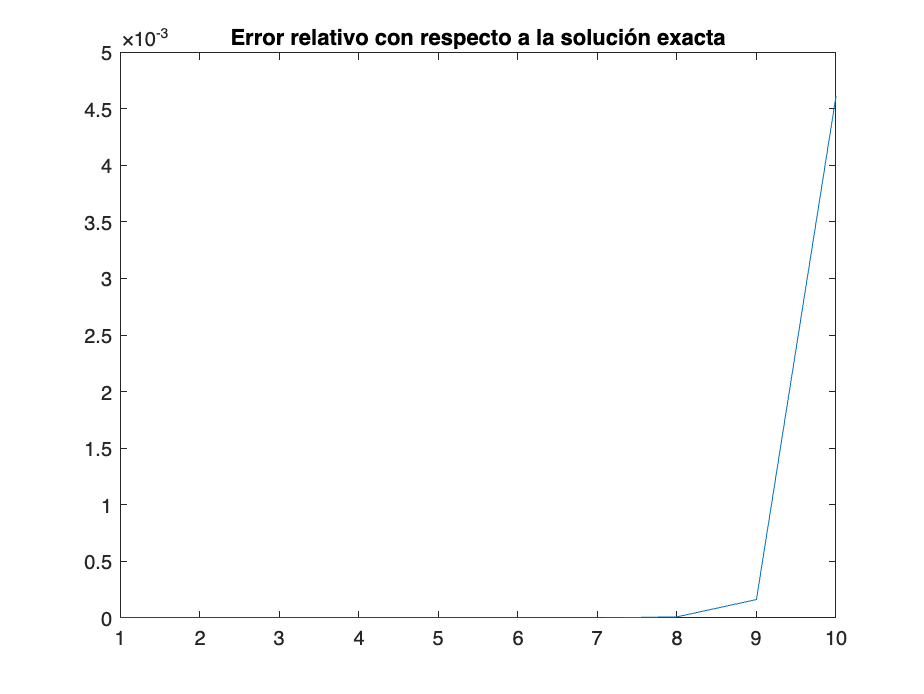

i=1;
n=20;
VecErHil=[];
VecErHil(1)=0;
VecEr=[];
VecEr(1)=0;
tol=1.e-2;
while(VecErHil(i)<=tol)
    i=1+i;
    A=hilb(i);
    b=A*ones(i,1);
    x=A\b;
    VecEr(i)=norm(x-ones(i,1))/norm(ones(i,1));
    VecErHil(i)=cond(A)*eps*2;

end
plot(VecEr(2:end))
title('Error relativo con respecto a la solución exacta')

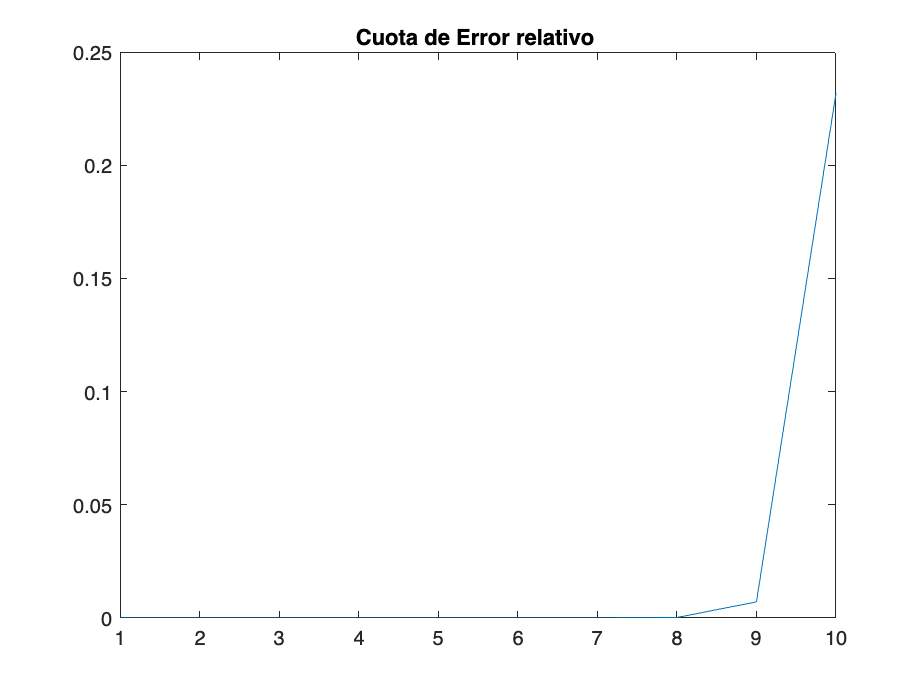


plot(VecErHil(2:end))

title('Cuota de Error relativo ')